# ME5554/AOE5754/ECE5754 Applied Linear Systems - Midterm Project

Name: Mohitha Mikkilineni     Submission Date: 11/16/2020

clear, clc
format short g
format compact

## Background

A small startup company has developed a concept for delivering packages (Payload).

This concept uses an open-top bin supported by drone motors and propellors.

Prior to developing a full 3D prototype, they have commissioned you to develop and validate 

a state-feedback control system for a 2D (i.e. planar) version as shown in Figure 1.

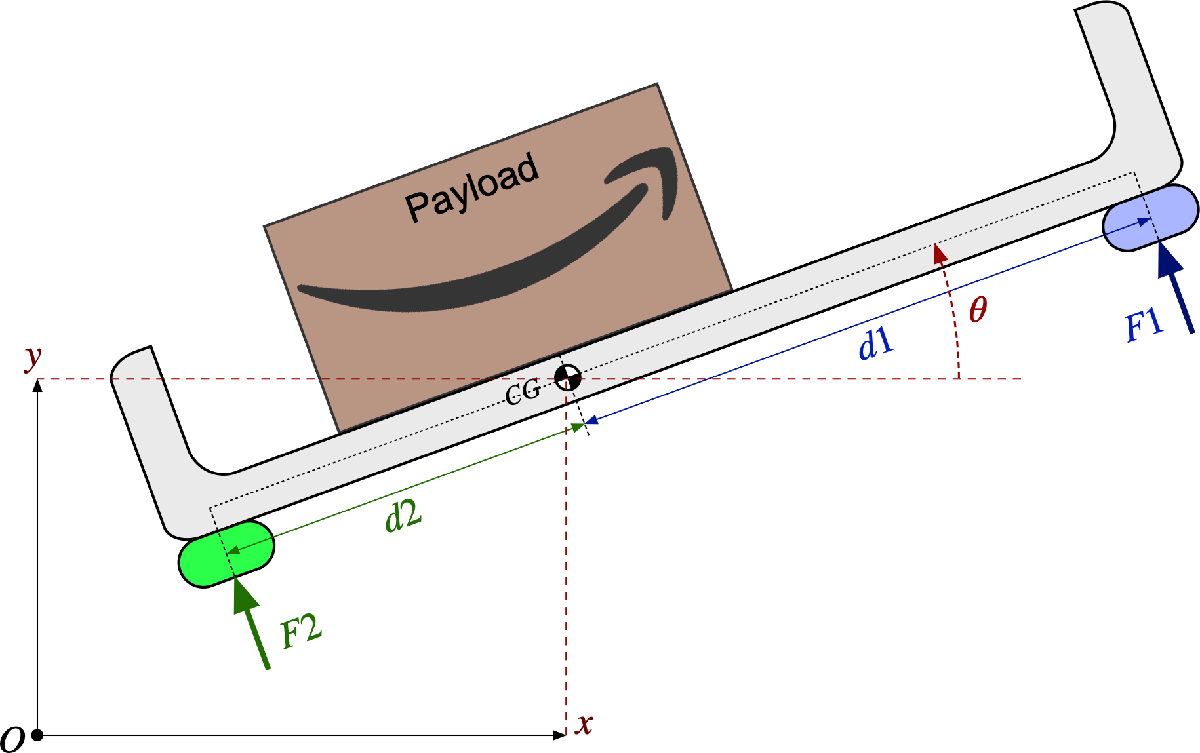

**Figure 1.  2D-Coordinate System Definition for Prototype Aerial Package Delivery System**

The following signal and geometry definitions refer to Figure 1:

        
$$\begin{array}{l}
\textrm{CG}=\textrm{center}\;\textrm{of}\;\textrm{gravity}\;\textrm{of}\;\textrm{the}\;\textrm{system}\;\textrm{with}\;\textrm{the}\;\textrm{current}\;\textrm{payload}\;\textrm{position}\\
O=\textrm{origin}\;\textrm{of}\;\textrm{the}\;\textrm{world}\;\textrm{coordinate}\;\textrm{system}\\
x\left(t\right)=\textrm{horizontal}\;\textrm{position}\;\left(\textrm{meters}\right)\;\textrm{of}\;\textrm{the}\;\textrm{CG}\;\textrm{in}\;\textrm{the}\;\textrm{world}\;\textrm{coordinate}\;\textrm{system}\\
y\left(t\right)=\textrm{vertical}\;\textrm{position}\;\left(\textrm{meters}\right)\;\textrm{of}\;\textrm{the}\;\textrm{CG}\;\textrm{in}\;\textrm{the}\;\textrm{world}\;\textrm{coordinate}\;\textrm{system}\\
\theta \left(t\right)=\textrm{angular}\;\textrm{rotation}\;\left(\textrm{radians}\right)\;\textrm{of}\;\textrm{the}\;\textrm{open}-\textrm{top}\;\textrm{bin}\\
F_1 \left(t\right)=\textrm{control}\;\textrm{thrust}\;\textrm{force}\;\left(\textrm{Newtons}\right)\;\textrm{at}\;\textrm{the}\;\textrm{front}\;\textrm{of}\;\textrm{the}\;\textrm{bin}\\
F_2 \left(t\right)=\textrm{control}\;\textrm{thrust}\;\textrm{force}\;\left(\textrm{Newtons}\right)\;\textrm{at}\;\textrm{the}\;\textrm{rear}\;\textrm{of}\;\textrm{the}\;\textrm{bin}
\end{array}$$


The equations of motion for this system are non-linear; however, 

the following linearized equations are a reasonable approximation.

**Force balance, z-direction: **     $M\ddot{\mathrm{y}} \left(t\right)=F_1 \left(t\right)+F_2 \left(t\right)-\alpha \dot{y} \left(t\right)-M\;g\;$  

**Moment balance about CG:**     $J\theta^¨ \left(t\right)={d_1 F}_1 \left(t\right)-{d_2 F}_2 \left(t\right)-\beta \theta^˙ \left(t\right)$  

**Force balance, x-direction: **    $M\ddot{x} \left(t\right)=-\left({\bar{F} }_1 +{\bar{F} }_2 \right)\theta \left(t\right)-\gamma \dot{x} \left(t\right)$ 

These equations have physical parameters which are defined as:

        
$$\begin{array}{l}
g=\textrm{gravitational}\;\textrm{acceleration}\;\left(m/s^2 \right)\\
M=\textrm{total}\;\textrm{mass}\;\left(\textrm{kg}\right)\;\textrm{of}\;\textrm{the}\;\textrm{system}\;\textrm{with}\;\textrm{payload}\\
J=\textrm{total}\;\textrm{rotational}\;\textrm{moment}\;\textrm{of}\;\textrm{inertia}\;\left(\textrm{kg}\;{\;m}^2 \right)\;\textrm{about}\;\textrm{the}\;\textrm{CG}\;\textrm{of}\;\textrm{the}\;\textrm{system}\;\textrm{with}\;\textrm{payload}\\
\alpha =\textrm{vertical}\;\textrm{aerodynamic}\;\textrm{damping}\;\textrm{coefficient}\;\;\left(N\;s/m\right)\\
\beta =\textrm{rotational}\;\textrm{aerodynamic}\;\textrm{damping}\;\textrm{coefficient}\;\left(N\;m\;s/\textrm{rad}\right)\\
\gamma =\textrm{horizontal}\;\textrm{aerodynamic}\;\textrm{damping}\;\textrm{coefficient}\;\left(N\;s/m\right)\\
d_1 =\textrm{distance}\;\left(\textrm{meters}\right)\;\textrm{from}\;\textrm{the}\;\textrm{CG}\;\textrm{to}\;\textrm{the}\;\textrm{front}\;\textrm{control}\;\textrm{thrust}\\
d_2 =\textrm{distance}\;\left(\textrm{meters}\right)\;\textrm{from}\;\textrm{the}\;\textrm{CG}\;\textrm{to}\;\textrm{the}\;\textrm{rear}\;\textrm{control}\;\textrm{thrust}
\end{array}$$


## Problem 1 [2 pts].  Equilibrium Thrust Forces

The two remaining variables in the x-direction force balance equation are defined as:

        
$$\begin{array}{l}
{\bar{F} }_1 =\textrm{the}\;\textrm{nominal}\;\textrm{nonzero}\;\textrm{front}\;\textrm{thrust}\;\left(\textrm{Newtons}\right)\;\textrm{to}\;\textrm{maintain}\;\textrm{an}\;\textrm{equilibrium}\;\textrm{hover}\;\textrm{condition}\\
{\bar{F} }_2 =\textrm{the}\;\textrm{nominal}\;\textrm{nonzero}\;\textrm{rear}\;\textrm{thrust}\;\left(\textrm{Newtons}\right)\;\textrm{to}\;\textrm{maintain}\;\textrm{an}\;\textrm{equilibrium}\;\textrm{hover}\;\textrm{condition}
\end{array}$$


Derive an analytic formula relating these two nominal equilibrium thrust values to the system parameters. 

Hint:  When the system is in Equilibrium, all derivatives in the ODE's must be zero!

**Reason:**

When the system is in equilibrium,  all derivatives in the ODE's are zero.

After equating all the ODE's to zero, we get

$F_1(t) + F_2(t) = M*g$;


$$d_1*F_1(t) = d_2*F_2(t);$$



$$-(\bar{F_{1}}+ \bar{F_2})*\theta =0;$$


At equilibrium, $$F_1(t)= \bar{F_1}$ and $  F_2(t)= \bar{F_2}$$

Solving the above equations, we get,

$\bar{F_1}= \frac{d_2 * M * g}{d_1 + d_2}$ in Newtons  

and

$\bar{F_2}= \frac{d_1 * M * g}{d_1 + d_2}$ in Newtons

## Problem 2 [2 pts].  Equations of Motion around the Operating Point

From the results above, rewrite the ODE's in terms of the "variational" forces 

$\left(u_1 ,u_2 \right)$ about the operating point (hover) using the following definitions:

    
$$F_1 \left(t\right)={\bar{F} }_1 +u_1 \left(t\right)$$
 

    
$$F_2 \left(t\right)={\bar{F} }_2 +u_2 \left(t\right)$$
 

%Problem 2
syms F_1(t) F_2(t) M g y_ddot(t) y_dot(t) J theta(t) alpha beta gamma x_dot(t) x_ddot(t) theta_dot(t) theta_ddot(t) d_1 d_2 F_bar_1 F_bar_2 
syms u_1(t) u_2(t)
%Given F_1(t)= F_bar_1 + u_1(t) and
%      F_2(t)= F_bar_2 +u_2(t)
% Rewriting the above ODE's from the results above in terms of the
% variational forces u_1(t) and u_2(t) about the operating point, we get
fprintf(' Equations of Motion around the Operating Point are: ');

 Equations of Motion around the Operating Point are: 

y_ddot(t) = -(alpha/M)*y_dot(t) + (1/M)*u_1(t) + (1/M)*u_2(t)

$$y\_ddot(t) = \frac{u_{1}\left(t\right)}{M}+\frac{u_{2}\left(t\right)}{M}-\frac{\alpha \,\dot{y}\left(t\right)}{M}$$


theta_ddot(t)= (d_1/J)*u_1(t)-(d_2/J)*u_2(t) - (beta/J)*theta_dot(t)

$$theta\_ddot(t) = \frac{d_{1}\,u_{1}\left(t\right)}{J}-\frac{\beta \,\dot{\theta }\left(t\right)}{J}-\frac{d_{2}\,u_{2}\left(t\right)}{J}$$

x_ddot(t) = -((F_bar_1 + F_bar_2)/M)*theta(t) - (gamma/M)*x_dot(t)

$$x\_ddot(t) = -\frac{\gamma \,\dot{x}\left(t\right)}{M}-\frac{\theta \left(t\right)\,\left({\bar{F}}_{1}+{\bar{F}}_{2}\right)}{M}$$

## Problem 3 [10 pts].  Analytic State-Space Model

Using the results from Problem 2, choose appropriate state variables 

and define a complete state-space representation for this system.

The outputs for this system are $\left(x,y,\theta \right)$.

%Problem 3

syms p p_dot q q_dot r s s_dot r_dot x y F_max v w w_dot v_dot
%Assuming the state variables to define a complete state-space
%representation for this system
% let p=y_dot;
%     p_dot=y_ddot;
%     q=theta_dot;
%     q_dot=theta_ddot;
%     r=theta;
%     r_dot=theta_dot;  %hence, r_dot=p
%     s=x_dot;
%     s_dot=x_ddot;
%     v=x;
%     w=y;
%     w_dot=p;
%     v_dot=s;
State_Vector_dot = [p_dot; q_dot; r_dot; s_dot; v_dot; w_dot];   
State_Vector = [p; q; r; s; v; w];
Input_Vector = [u_1; u_2];
Output_Vector = [x; y; theta];
% Coefficients of p_dot, q_dot, r_dot, s_dot, v_dot; w_dot
A=[-(alpha/M), 0, 0, 0,0,0;...
    0, -(beta/J), 0 ,0,0,0;...
    0,           1,0,0,0,0;...
    0,0,-((F_bar_1+F_bar_2)/M),-(gamma/M),0,0;...
    0,0,0, 1 ,         0,0;...
    1,0,0, 0 ,         0,0];      
B= [1/M  , 1/M  ;...
    d_1/J, -d_2/J;...
         0,    0;...
         0,    0;...
         0,    0;...
         0,   0];
C=[0,0,0,0,1,0;...
   0,0,0,0,0,1;...
   0,0,1,0,0,0];
D=zeros(3,2);
% State-Space Representation:
%State_Vector_dot = A * State_Vector + B * Input_Vector;
%Output_Vector=C*State_Vector + D*Input_Vector

fprintf(' Matrix A for the State Space Model is: ');

 Matrix A for the State Space Model is: 

disp(A);

$$\left(\begin{array}{cccccc} -\frac{\alpha }{M} & 0 & 0 & 0 & 0 & 0\\ 0 & -\frac{\beta }{J} & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & -\frac{{\bar{F}}_{1}+{\bar{F}}_{2}}{M} & -\frac{\gamma }{M} & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 1 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$


fprintf(' Matrix B for the State Space Model is: ');

 Matrix B for the State Space Model is: 

disp(B);

$$\left(\begin{array}{cc} \frac{1}{M} & \frac{1}{M}\\ \frac{d_{1}}{J} & -\frac{d_{2}}{J}\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0 \end{array}\right)$$


fprintf(' Matrix C for the State Space Model is: ');

 Matrix C for the State Space Model is: 

disp(C);

     0     0     0     0     1     0
     0     0     0     0     0     1
     0     0     1     0     0     0



fprintf(' Matrix D for the State Space Model is: ');

 Matrix D for the State Space Model is: 

disp(D);

     0     0
     0     0
     0     0


State-Space State Equation:


$$$$\left( \begin{array}{c} \dot{p} \\ \dot{q} \\\dot{r} \\ \dot{s}\\\dot{v} \\ \dot{w} \end{array} \right)=\left( \begin{array}{cccccc} \frac{-\alpha}{M }& 0 & 0 &0 & 0 &0 \\ 0 & \frac{-\beta}{J} & 0& 0&0 &0 \\ 0 & 1 & 0& 0&0&0 \\ 0&0&\frac{ -(\bar{F_1}+ \bar{F_2})}{M}  
&\frac{-\gamma}{M} & 0& 0\\ 0& 0&0&1&0&0 \\ 1&0&0&0&0&0 \end{array} \right) \left(\begin{array}{c}p\\q\\r\\s\\v\\w \end{array}\right) + \left( \begin{array}{cc} \frac{1}{M}&\frac{1}{M} \\ \frac{d_1}{J} & \frac{-d_2}{J} \\0&0 \\ 0&0\\0&0 \\ 0&0 \end{array}\right)\left( \begin{array}{c} u_1 \\ u_2 \end{array} \right) $$$$


State-Space Output Equation:


$$$$\left( \begin{array}{c} x \\ y \\\theta \end{array} \right)=\left( \begin{array}{ccc} 0 & 0 & 0 &0 & 1 &0 \\ 0 & 0 & 0& 0&0 &1 \\ 0 & 0 & 1 & 0&0&0  \end{array} \right) \left(\begin{array}{c}p\\q\\r\\s\\v\\w \end{array}\right) + \left( \begin{array}{cc} 0&0\\0&0 \\ 0&0 \end{array}\right)\left( \begin{array}{c} u_1 \\ u_2 \end{array} \right) $$
$$


## Problem 4 [4 pts].  Define system parameters as Matlab variables

Define Matlab variables for the following parameters:

        
$$\begin{array}{l}
g=9\ldotp 81\;\left(m/s^2 \right)\\
M=15\;\left(\textrm{kg}\right)\;\\
J=3\;\left(\textrm{kg}\;{\;m}^2 \right)\;\\
\alpha =30\;\left(N\;s/m\right)\\
\beta =5\;\left(N\;m\;s/\textrm{rad}\right)\\
\gamma =10\;\left(N\;s/m\right)\\
d_1 =0\ldotp 651\;\left(\textrm{meters}\right)\;\\
d_2 =0\ldotp 449\;\left(\textrm{meters}\right)\;\\
F_{\max } =2000\;\left(N\right)\;\;\;\;\;\textrm{maximum}\;\textrm{available}\;\textrm{thrust}\;\textrm{on}\;\textrm{either}\;F_1 \;\textrm{or}\;F_2 
\end{array}$$


%Problem 4

%defining Matlab variables for the following parameters:
g=9.81;        %gravitational acceleration (m/s^2)
M=15;          %total mass(kg) of the system with payload
J=3;           %total rotational moment of inertia(kg•m^2) about the CG of the system with payload
alpha=30;      %vertical aerodynamic damping coefficient(N•s/m)
beta=5;        %rotational aerodynamic damping coefficient(N•m•s/rad)
gamma=10;      %horizontal aerodynamic damping coefficient(N•s/m)
d_1=0.651;     %distance(meters) from the CG to the front control thrust
d_2=0.449;     %distance(meters) from the CG to the rear control thrust
F_max=2000;    %Maximum available thrust(N) on either F_1 or F_2 (2e3=2*10^3 )

Compute the nominal equlibrium thrust forces and the maximum variational forces.

currentPrecision = digits;
digitsOld = digits(7); %setting the precision to desired digits

%Computing the nominal equilibrium thrust forces: F_bar-1 and F_bar_2
F_bar_1= (d_2 * M * g)/(d_1 + d_2);
F_bar_2=(d_1 * M * g)/(d_1 + d_2);

fprintf('Nominal equilibrium thrust forces(N):');

Nominal equilibrium thrust forces(N):

disp(F_bar_1); 

       60.064


disp(F_bar_2);

       87.086




%Computing the maximum variational forces:u_1(t) and u_2(t)
u_1(t)= F_max - F_bar_1; 
u_2(t)= F_max-F_bar_2; 
u_1=double(vpa(subs(u_1(t))));
u_1_max=vpa(u_1);
u_2=double(vpa(subs(u_2(t))));
u_2_max=vpa(u_2);
fprintf('Maximum variational forces (N) :');

Maximum variational forces (N) :

disp(u_1_max);

$$1939.936$$

disp(u_2_max);

$$1912.914$$

## Problem 5 [5 pts].   Numerical State-space model with state, input, and output names

Construct an LTI State-Space object in Matlab using the defined variables from Problem 4.

Define state, input, and output names, as well as state, input, and output units, and embed them in the LTI object.

%Problem 5

%Using 'subs' to find the matrices after substituting the given numeric
%parameters
% Using 'double' to convert symbolic array to numeric array

A_Num = double(subs(A));
B_Num = double(subs(B));
fprintf(' Matrix A for the State Space Model is: ');

 Matrix A for the State Space Model is: 

disp(A_Num);

           -2            0            0            0            0            0
            0      -1.6667            0            0            0            0
            0            1            0            0            0            0
            0            0        -9.81     -0.66667            0            0
            0            0            0            1            0            0
            1            0            0            0            0            0




fprintf(' Matrix B for the State Space Model is: ');

 Matrix B for the State Space Model is: 

disp(B_Num);

     0.066667     0.066667
        0.217     -0.14967
            0            0
            0            0
            0            0
            0            0


fprintf(' Matrix C for the State Space Model is: ');

 Matrix C for the State Space Model is: 

disp(C);

     0     0     0     0     1     0
     0     0     0     0     0     1
     0     0     1     0     0     0




fprintf(' Matrix D for the State Space Model is: ');

 Matrix D for the State Space Model is: 

disp(D);

     0     0
     0     0
     0     0


Therefore, the state-space representation with numeric values is

State-space state equation:


$$$$\left( \begin{array}{c} \dot{p} \\ \dot{q} \\\dot{r} \\ \dot{s}\\\dot{v} \\ \dot{w} \end{array} \right)=\left( \begin{array}{cccccc} -2& 0 & 0 &0 & 0 &0 \\ 0 & -1.6667 & 0& 0&0 &0 \\ 0 & 1 & 0& 0&0&0 \\ 0&0& -9.81
&-0.66667 & 0& 0\\ 0& 0&0&1&0&0 \\ 1&0&0&0&0&0 \end{array} \right) \left(\begin{array}{c}p\\q\\r\\s\\v\\w \end{array}\right) + \left( \begin{array}{cc} 0.066667&0.066667 \\ 0.217 & -0.14967\\0&0 \\ 0&0\\0&0 \\ 0&0 \end{array}\right)\left( \begin{array}{c} u_1 \\ u_2 \end{array} \right) $$$$


State-Space Output  equation:


$$$$\left( \begin{array}{c} x \\ y \\\theta \end{array} \right)=\left( \begin{array}{ccc} 0 & 0 & 0 &0 & 1 &0 \\ 0 & 0 & 0& 0&0 &1 \\ 0 & 0 & 1 & 0&0&0  \end{array} \right) \left(\begin{array}{c}p\\q\\r\\s\\v\\w \end{array}\right) + \left( \begin{array}{cc} 0&0\\0&0 \\ 0&0 \end{array}\right)\left( \begin{array}{c} u_1 \\ u_2 \end{array} \right) $$
$$



% LTI State-Space object using the defined variables
ol_sys=ss(A_Num, B_Num, C, D);
%Defining state, input, and output names, as well as state, input, and output units, 
set(ol_sys, 'StateName', {'Velocity of the CG in the vertical direction  (p)'; 'Angular velocity (q) of the open-top bin'; 'Angular rotation of the open-top bin (r)'; ...
                         'Velocity of the CG in the horizontal direction (s)';'Horizontal position of the CG in the world coordinate system(v)'; ...
                         'Vertical position of the CG  in the world coordinate system (w)'},...
            'StateUnit', {'m/s'; 'rad/s'; 'rad'; 'm/s';'m';'m'},...
            'InputName', {'Variational force (u_1(t)) about the operating point'; 'Variational force (u_2(t) about the operating point '},...
            'InputUnit', {'N'; 'N'},...    
            'OutputName', {'Horizontal position of the CG in the world coordinate system(x)'; 'Vertical position of the CG  in the world coordinate system (y)'; ...
                           'Angular rotation of the open-top bin(theta)'},...
            'OutputUnit', {'m'; 'm'; 'rad'})
fprintf('LTI State Space object is: ');

LTI State Space object is: 

disp(ol_sys);

  3×2 ss array with properties:

                A: [6×6 double]
                B: [6×2 double]
                C: [3×6 double]
                D: [3×2 double]
                E: []
           Scaled: 0
        StateName: {6×1 cell}
        StateUnit: {6×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: [2×1 double]
      OutputDelay: [3×1 double]
               Ts: 0
         TimeUnit: 'seconds'
        InputName: {2×1 cell}
        InputUnit: {2×1 cell}
       InputGroup: [1×1 struct]
       OutputName: {3×1 cell}
       OutputUnit: {3×1 cell}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
     SamplingGrid: [1×1 struct]


%defined state names embedded in the LTI state-space model
ol_sys

ol_sys =
 
  A = 
                  Velocity of  Angular velo  Angular rota   Velocity of  Horizontal p  Vertical pos
   Velocity of             -2             0             0             0             0             0
   Angular velo             0        -1.667             0             0             0             0
   Angular rota             0             1             0             0             0             0
   Velocity of              0             0         -9.81       -0.6667             0             0
   Horizontal p             0             0             0             1             0             0
   Vertical pos             1             0             0             0             0             0
 
  B = 
                  Variational   Variational
   Velocity of        0.06667       0.06667
   Angular velo         0.217       -0.1497
   Angular rota             0             0
   Velocity of              0             0
   Horizontal p             0             0
   Vertic

## Problem 6 [2 pts].  Check for minimum realization

Determine whether the open-loop state-space model is a minimum realization, and explain why.

**Reason: ** The state-space model is said to be a minimum realization when the system has minimum number of states required to describe a system. Since the state-space model has minimum number of states, hence the open-loop state-space model is a minimum realization.

%Problem 6
ol_sys_minreal = minreal(ol_sys); %minimum realization
% To determine if the State Space Model is the minimum realization
if(isequal(ol_sys_minreal.A,A_Num) && isequal(ol_sys_minreal.B,B_Num)...
        && isequal(ol_sys_minreal.C,C) && isequal(ol_sys_minreal.D,D))
    fprintf(' The open-loop state-space model is a minimum realization ');
    
else
    fprintf(' The open-loop state-space model is not a minimum realization ');
    
end

 The open-loop state-space model is a minimum realization 

## Problem 7 [5 pts].  Controllability test

**Demonstrate that the open-loop system is completely controllable, and explain why.**

**Reason:** We know that, the system is controllable if the rank of controllability matrix is equal to the maximum possible rank. 

Therefore, if the column vectors of controllablity matrix $\textrm{Co}=\left\lbrack B,\textrm{AB},A^2 B,A^3 B,\ldotp \ldotp \ldotp \ldotp A^{N-1} B\right\rbrack$span the N-dimensional space. This is equivalent to Co having rank **N**.

For the given open-loop system to be completely controllable, the rank of controllability matrix must be equal to the its maximum possible rank.

Here, the rank of the controllability matrix(**N**) is 6, and thus Co matrix is full rank iff **N**=6 since number of columns of matrix B is 6

%Problem 7

%To demonstrate the open-loop system is completely controllable
Co = ctrb(A_Num,B_Num);   %returns the Controllability matrix
Co_rank= rank(Co);
fprintf(' The rank of the controllability matrix is: ');

 The rank of the controllability matrix is: 

disp(Co_rank);

     6


%Full rank is 6
if Co_rank == 6
    fprintf('Hence the LTI system is completely controllable ');
else
    fprintf('Hence the LTI system is not completely controllable ')
end

Hence the LTI system is completely controllable 

**Determine if the system is controllable with only one actuator (check both!), and explain why.**

**Reason:** We know that, the system is controllable if the rank of controllability matrix is equal to the maximum possible rank. 

Therefore, if the column vectors of controllablity matrix $\textrm{Co}=\left\lbrack B,\textrm{AB},A^2 B,A^3 B,\ldotp \ldotp \ldotp \ldotp A^{N-1} B\right\rbrack$

span the** N**-dimensional space. This is equivalent to Co having rank **N**.

For the given  system  with only one actuator to be completely controllable, the rank of controllability matrix must be equal to its maximum possible rank.

Here, the rank of the controllability matrix is 5, and the **N**=6 since number of columns of matrix B is 6. Since, the rank of controllability matrix is not equal to its maximum possible rank. Hence, the system with

only one actuator is not controllable.

%To determine the system is controllable with only one actuator
%Determining the system is controllable with actuator (input:u_1)
B_with_u_1 = B_Num;
B_with_u_1(:,2) = zeros(6,1);
Co_with_u_1 = ctrb(A_Num,B_with_u_1);
Co_rank_with_u_1 = rank(Co_with_u_1);
fprintf(' The rank of the controllability matrix with only one actuator(u_1) is: ');

 The rank of the controllability matrix with only one actuator(u_1) is: 

disp(Co_rank_with_u_1);

     5


if Co_rank_with_u_1 == 6
    fprintf('Hence the LTI system is controllable ');
else
    fprintf('Hence the LTI system is not controllable ')
end

Hence the LTI system is not controllable 

%Determining the system is controllable with actuator (input:u_1)
 B_with_u_2= B_Num;
B_with_u_2(:,1) = zeros(6,1);
Co_with_u_2 = ctrb(A_Num,B_with_u_2);
Co_rank_with_u_2 = rank(Co_with_u_2);
fprintf(' The rank of the controllability matrix with only one actuator(u_2) is: ');

 The rank of the controllability matrix with only one actuator(u_2) is: 

disp(Co_rank_with_u_2);

     5


if Co_rank_with_u_2 == 6
    fprintf('Hence the LTI system is controllable ');
else
    fprintf('Hence the LTI system is not controllable ')
end

Hence the LTI system is not controllable 

## Problem 8 [5 pts].  Open-loop poles & natural frequencies

Compute the open-loop eigenvalues, damping ratios, time constants, and natural frequencies in Hz.

% Problem 8.
%To compute the open-loop eigenvalues, damping ratios, time constants and
%natural frequencies in Hz

%To compute the open-loop eigenvalues
eig_val = eig(A_Num);
fprintf(' The open-loop eigen values are: ');

 The open-loop eigen values are: 

disp(eig_val);

            0
           -2
            0
     -0.66667
            0
      -1.6667


% Using function 'damp' to compute poles, natural frequency and damping
% ratio
[wn, zeta, p] = damp(ol_sys);
damp(ol_sys) %Displayed poles are in increasing order

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
  0.00e+00    -1.00e+00       0.00e+00              Inf    
  0.00e+00    -1.00e+00       0.00e+00              Inf    
  0.00e+00    -1.00e+00       0.00e+00              Inf    
 -6.67e-01     1.00e+00       6.67e-01         1.50e+00    
 -1.67e+00     1.00e+00       1.67e+00         6.00e-01    
 -2.00e+00     1.00e+00       2.00e+00         5.00e-01    


Wn = wn/(2*pi);  %converting natural frequencies(rad/sec) to Hz
tau=1./(wn.*zeta); %Time Constant

fprintf(' The Open-loop eigen values(poles(P)),damping ratios(Z), natural frequencies(Wn) and time constants are: ');

 The Open-loop eigen values(poles(P)),damping ratios(Z), natural frequencies(Wn) and time constants are: 

T = table(p, zeta, Wn, abs(tau));
T.Properties.VariableNames = {'EigenValues or Poles', 'DampingRatios','NaturalFrequencies (Hz)','TimeConstants (seconds)'};
disp(T);

    EigenValues or Poles    DampingRatios    NaturalFrequencies (Hz)    TimeConstants (seconds)
    ____________________    _____________    _______________________    _______________________
                 0               -1                        0                      Inf          
                 0               -1                        0                      Inf          
                 0               -1                        0                      Inf          
          -0.66667                1                   0.1061                      1.5          
           -1.6667                1                  0.26526                      0.6          
                -2                1                  0.31831                      0.5          


## Problem 9 [10 pts].  Open-Loop Initial Value response simulation

Assume that the system starts with the following initial positions and velocities:

    $x\left(0\right)=-2$ m, $y\left(0\right)=1$ m, and $\theta \left(0\right)=0\ldotp 5$ rad.

    $\dot{x} \left(0\right)=10$ m/s, $\dot{y} \left(0\right)=-1\ldotp 5$ m/s, and $\theta^˙ \left(0\right)=-0\ldotp 5$ rad/s.

Use the Matlab INITIAL function to compute the initial value response.

Choose a final time that is four times the largest open-loop time constant.

Plot the initial value response.  There must be three subplots on the left of the figure,

one for each of the outputs, and two subplots on the right, one for each control signal.

All subplots must be properly annotated with axis labels, units, and grid lines.

The control output plots must also indicate the upper and lower saturation constraints for the signals.

Use the LSIMINFO function to estimate the 5% settling time for each OUTPUT,

and place a marker on each output plot at the location of its 5% settling time.

%Problem 9

%Assuming that the system starts with the following initial positions and
%velocities

% Initial condition for output responses
x_0 = -2;           % m
y_0 = 1;            % m
theta_0 = 0.5;      % rad

% Initial condition for State Variables
p_0 = -1.5;          % m/s
q_0 = -0.5;          % m/s
r_0 = 0.5;           % rad
s_0= 10;             %rad/s
v_0=-2;              %m
w_0=1;               %m

State_Vector_0 = [p_0; q_0; r_0; s_0;v_0;w_0];
Tfinal=4*max(tau); %Final Time

%Simulate the unforced response of a state-space (ss) model ol_sys with an initial condition on the states specified by the vector State_Vector_0:
% let Y be the outputs (x, y, theta) 
% and X be the state response (p, q, r,s, x, y, theta)
[Y,T,X] = initial(ol_sys,State_Vector_0,Tfinal);


% We know that the default settling time of LSIMINFO is 2%, so, we need to
% change it to 5% for both state responses (X) and the output Responses (Y)
% as mentioned
X_State = lsiminfo(X,T,'SettlingTime',0.05);
Y_Output = lsiminfo(Y,T,'SettlingTime',0.05);

% Converting LSIMINFO structure to a table for display purposes
XTable = struct2table(X_State); 

% Converting LSIMINFO structure to a table for display purposes
YTab = struct2table(Y_Output); 

% Horizontal Position (m) of the CG in the world coordinate system at 5% Settling time, 
HorizontalPosition_SettlingTime = interp1(T(:,1),Y(:,1),YTab.SettlingTime(1));
disp(' Horizontal Position (x) at 5% Settling time: ');

 Horizontal Position (x) at 5% Settling time: 


fprintf('Time = %.4f s, HorizontalPosition(x) = %.4f m', YTab.SettlingTime(1), HorizontalPosition_SettlingTime);

Time = 5.8538 s, HorizontalPosition(x) = -2.7650 m

% Vertical Position (m) of the CG in the world coordinate system at 5% Settling time,
VerticalPosition_SettlingTime = interp1(T(:,1),Y(:,2),YTab.SettlingTime(2));
disp(' VerticalPosition (y) at 5% Settling time: ');

 VerticalPosition (y) at 5% Settling time: 


fprintf('Time = %.4f s, VerticalPosition (y) = %.4f m', YTab.SettlingTime(2), VerticalPosition_SettlingTime);

Time = 1.4983 s, VerticalPosition (y) = 0.2875 m


% Angular position (rad) of the open-top bin at 5% Settling time
AngularPosition_SettlingTime = interp1(T(:,1),Y(:,3),YTab.SettlingTime(3));
disp('Angular position (theta) at 5% Settling time: ');

Angular position (theta) at 5% Settling time: 


fprintf('Time = %.4f s, AngularPosition(theta) = %.4f rad', YTab.SettlingTime(3), AngularPosition_SettlingTime);

Time = 1.7975 s, AngularPosition(theta) = 0.2150 rad

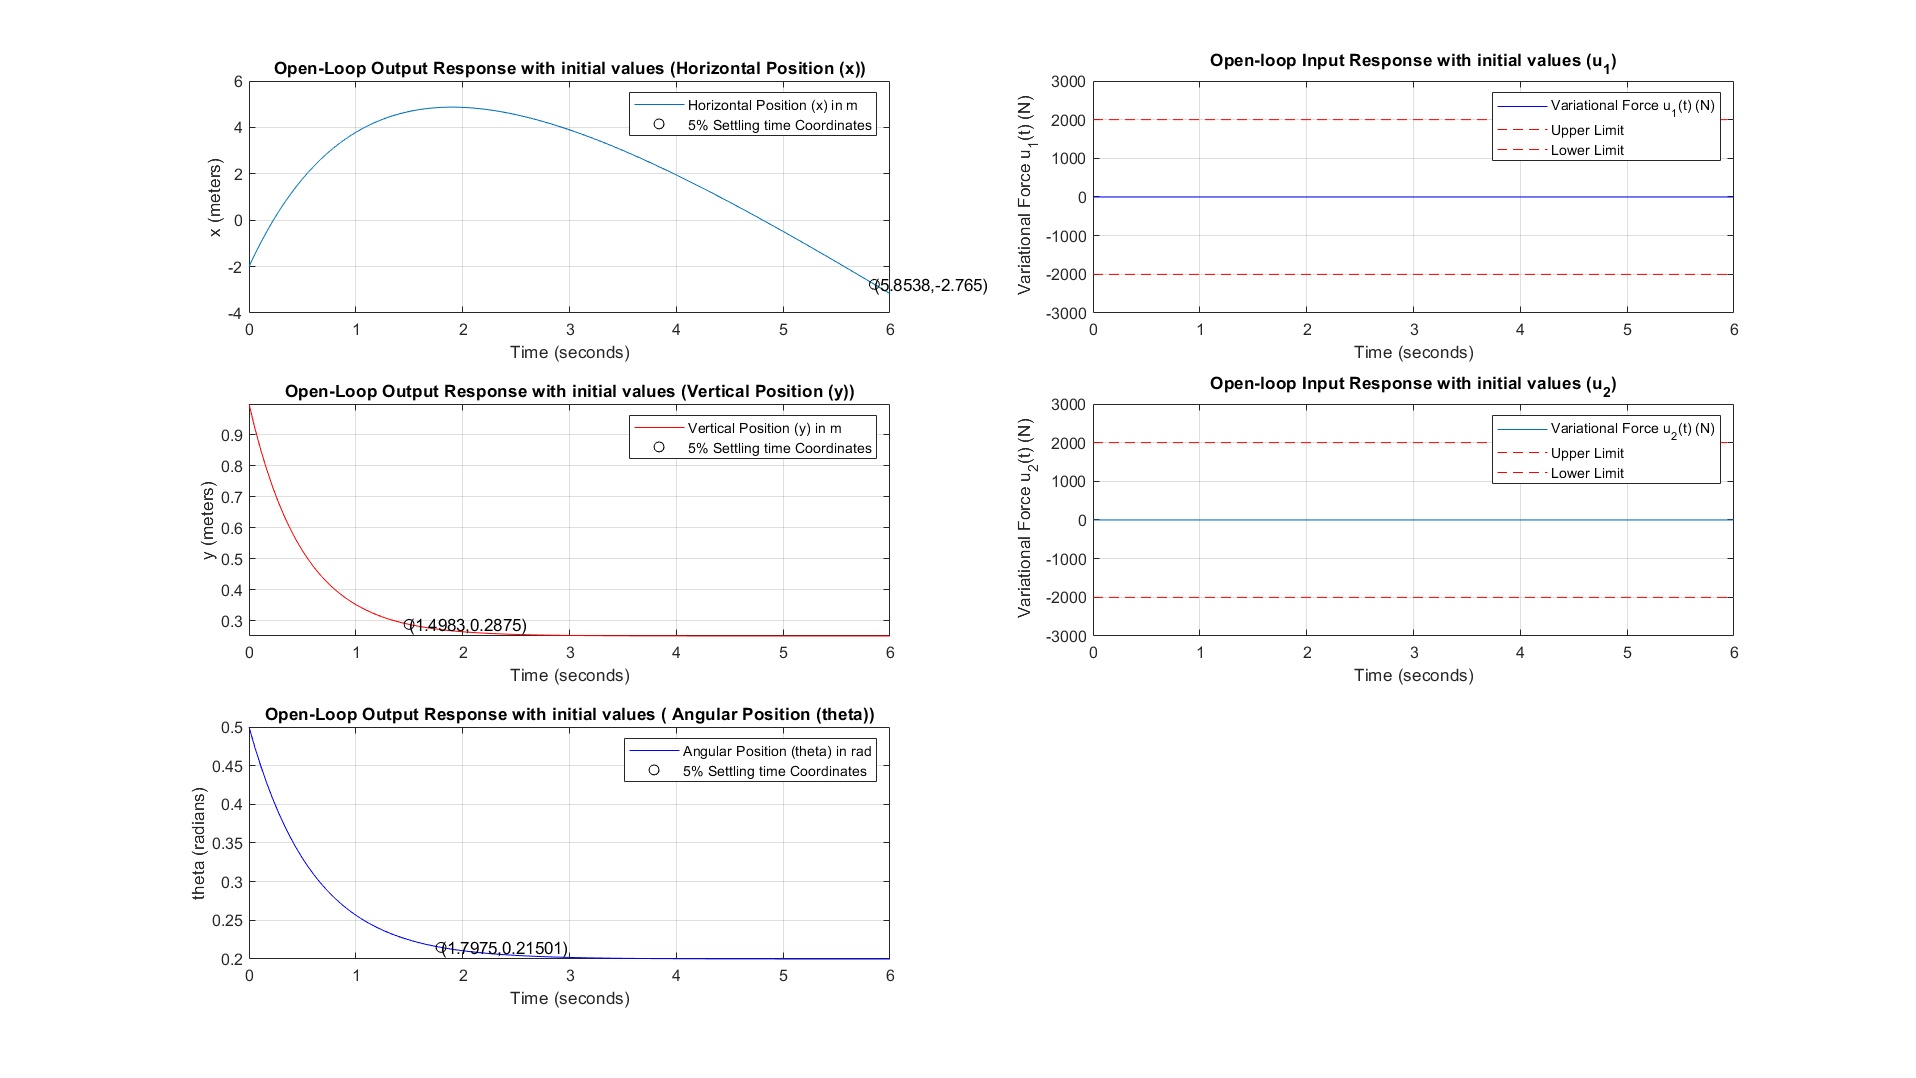

  
figure();
yyaxis left
% Open-Loop Output Response with initial values (Horizontal Position (x))
subplot(3,2,1);
plot(T,Y(:,1));
grid on
hold on
title(['Open-Loop Output Response with initial values (Horizontal Position (x))']);
xlabel('Time (seconds)')
ylabel('x (meters)')
plot(YTab.SettlingTime(1),HorizontalPosition_SettlingTime,'kO');
text(YTab.SettlingTime(1), HorizontalPosition_SettlingTime,['(' num2str(YTab.SettlingTime(1)) ',' num2str(HorizontalPosition_SettlingTime) ')']);
legend('Horizontal Position (x) in m', '5% Settling time Coordinates', '');

%Open-Loop Output Response with initial values (Vertical Position (y))
subplot(3,2,3);
plot(T,Y(:,2),'r');
grid on
hold on
title(['Open-Loop Output Response with initial values (Vertical Position (y))']);
xlabel('Time (seconds)')
ylabel('y (meters)')
ylim([0.25 1])
xlim([0 6])
plot(YTab.SettlingTime(2), VerticalPosition_SettlingTime,'kO');
text(YTab.SettlingTime(2),VerticalPosition_SettlingTime,['(' num2str(YTab.SettlingTime(2)) ',' num2str(VerticalPosition_SettlingTime) ')']);
legend('Vertical Position (y) in m', '5% Settling time Coordinates', '');

%Open-Loop Output Response with initial values ( Angular Position (theta))
subplot(3,2,5);
plot(T,Y(:,3),'b');
grid on
hold on
title(['Open-Loop Output Response with initial values ( Angular Position (theta))']);
xlabel('Time (seconds)')
ylabel('theta (radians)');
plot(YTab.SettlingTime(3),AngularPosition_SettlingTime,'kO');
text(YTab.SettlingTime(3),AngularPosition_SettlingTime ,['(' num2str(YTab.SettlingTime(3)) ',' num2str(AngularPosition_SettlingTime) ')']);
legend('Angular Position (theta) in rad','5% Settling time Coordinates', '');

%Open-loop Input Response with initial values (u_1)
subplot(3,2,2);
ControlInput_1 = zeros(110,1);
plot(T,ControlInput_1,'b');
grid on
hold on
hRefl=refline(0,2e3);
set(hRefl,'color','r','linestyle','--'); 
hRef2=refline(0,-2e3);
set(hRef2,'color','r','linestyle','--'); 
title('Open-loop Input Response with initial values (u_1)');
xlabel('Time (seconds)')
ylabel(' Variational Force u_1(t) (N)')
ylim([-3e3 3e3])
legend('Variational Force u_1(t) (N)','Upper Limit','Lower Limit');

%Open-loop Input Response with initial values (u_2)
subplot(3,2,4);
ControlInput_2 = zeros(110,1);
plot(T,ControlInput_2);
grid on
hold on
hRefl=refline(0,2e3);
set(hRefl,'color','r','linestyle','--'); 
hRef2=refline(0,-2e3);
set(hRef2,'color','r','linestyle','--'); 
title('Open-loop Input Response with initial values (u_2)');
xlabel('Time (seconds)')
ylabel(' Variational Force u_2(t) (N)')
ylim([-3e3 3e3])
legend('Variational Force u_2(t) (N)','Upper Limit','Lower Limit');

set(gcf, 'Units', 'Normalized', 'Position', [1, 1, 1, 1]);

warning('off')

**Provide a physical explanation for the open-loop response. ** 

**Reason**:

We can observe from the above graphs, the open-loop output and input responses of the given system. 

For output responses, we observe that the system enters steady state and becomes stable. One of the advantages of the open-loop system is it has no instability which can be observed from the above plots.

From, the above plots we can conclude that the open-loop output responses become steady after sometime.

The intial value of input responses are zero. 

**Why does the steady-state response look the way it does?**

**Reason:** We know that steady state occurs after the system becomes settled and doesn't change with time. Since, this is a open-loop system, the response becomes steady after a certain time and the response

 become stable.

## Problem 10 [15 pts].  Closed-Loop Design Case Study

Document at least five separate closed-loop pole locations for full state feedback.

The target design requirements are:

- The 5% settling times for any of the outputs must be less than 3 seconds

- The peak absolute variational control signal must not exceed the saturation limits

Note:  It is ok if an intermediate design does not meet the design requirements; however, at least

two of the five designs must meet the design requirements!  You must show creativity in your

design selection!

For each design, document the following:

- 5% settling times on each of the output responses

- Peak absolute control for each of the control signals

- Does either of your closed-loop control signals exceed the saturation limits?

- Why you chose this set of pole locations for the design?

You must use the PLACE function for each of your designs to compute the state feedback gains.

Develop a closed-loop LTI model that includes your three outputs as well as the two control signals.

Use the Matlab INITIAL function to compute the initial value response with the same 

initial condition vector that was used in the open-loop evaluation.

Choose a final time that is fifteen times the largest open-loop time constant.

Plot the initial value response.  There must be three subplots on the left of the figure,

one for each of the outputs, and two subplots on the right, one for each control signal.

All subplots must be properly annotated with axis labels, units, and grid lines.

The control output plots must also show the upper and lower saturation constraints for the signals.

Use the LSIMINFO function to estimate the 5% settling time for each OUTPUT,

and place a marker on each output plot at the location of its 5% settling time.

Note:  The 5% settling times are NOT required for the control signals!

**Reason****:**

**Given requirements:**


$$(i)|\bar{F_1|}  \leq F_{max}

$$



$$(ii)|\bar{F_2|}  \leq F_{max}  $$
 
$$where$$
 
$$F_{\max }$$

$$=2000\;N$$


**The target design requirements are:**

$(i)$Select the desired closed-loop pole locations for full state feedback.

$(ii)$The 5% settling times for any of the outputs must be less than 3 seconds.

$(iii)$The peak absolute variational control signal must not exceed the saturation limits.

**Simulation Requirements:**

$(i)$Given 5% settling times for any of the outputs must be less than 3 seconds


$$\Rightarrow T_s < 3
$$


Also, $|u_{peak}| < |u_{max}|
$

$|u_{peak}|<|GX|$ where G is Gain matrix and X is state vector

$(ii)$Peak absolute control for each of the control signals

$u_{1{max}}=1939. 
$936    and $u_{1_{min}}= -u_{1_{max}}$ $\Rightarrow u_{1}  $ lies in the range of (-1939.936,1939.936)

$u_{2_{max}}=1912.$914   and $u_{2_{min}}= -u_{2_{max}}$   $\Rightarrow u_{2}$ lies in the range of (-1912.914,1912.914)

Also,$u_1<u_{1_{max}}$ and $u_2<u_{2_{max}}$.

**Design 1:**

(i)  Select poles such  that all are all real.

% Problem 10

%Design_1
% select poles which are all real.
P1 = [-1.4; -2.1; -3.9;-2; -1.7; -3.1]; % desired closed-loop pole locations
G1 = place(A_Num, B_Num, P1); % Gain Matrix
Ac1 = A_Num - B_Num*G1;       %Matrix A for closed-loop system
cl_sys1 = ss(Ac1, B_Num, C, D); %Closed-loop LTI model
Tfinal1=6*abs(max(tau));      %Final time
%Compute the Initial Value response
[Y1,T1,X1] = initial(cl_sys1, State_Vector_0, Tfinal1);

Y_Output = lsiminfo(Y1,T1,'SettlingTime',0.05);

% Converting LSIMINFO structure to a table for display purposes
YTable = struct2table(Y_Output); 

 Horizontal Position (x) at 5% Settling time: 


Time = 4.1064 s, HorizontalPosition(x) = 0.1298 m

% Horizontal Position (m) of the CG in the world coordinate system at 5% Settling time, 
HorizontalPosition_SettlingTime1 = interp1(T1(:,1),Y1(:,1),YTable.SettlingTime(1));
disp(' Horizontal Position (x) at 5% Settling time: ');

 VerticalPosition (y) at 5% Settling time: 


fprintf('Time = %.4f s, HorizontalPosition(x) = %.4f m', YTable.SettlingTime(1), HorizontalPosition_SettlingTime1);

Time = 2.8306 s, VerticalPosition (y) = -0.0500 m

% Vertical Position (m) of the CG in the world coordinate system at 5% Settling time,
VerticalPosition_SettlingTime1 = interp1(T1(:,1),Y1(:,2),YTable.SettlingTime(2));
disp(' VerticalPosition (y) at 5% Settling time: ');
fprintf('Time = %.4f s, VerticalPosition (y) = %.4f m', YTable.SettlingTime(2), VerticalPosition_SettlingTime1);

Angular position (theta) at 5% Settling time: 


Time = 1.9677 s, AngularPosition(theta) = 0.0409 rad

% Angular position (rad) of the open-top bin at 5% Settling time
AngularPosition_SettlingTime1 = interp1(T1(:,1),Y1(:,3),YTable.SettlingTime(3));
disp('Angular position (theta) at 5% Settling time: ');
fprintf('Time = %.4f s, AngularPosition(theta) = %.4f rad', YTable.SettlingTime(3), AngularPosition_SettlingTime1);

ControlInput1 = abs(G1*X1');

  Peak absolute variational control signal (u_1) is:     15 N 

controlPeak1 = max(max(ControlInput1));

  Peak absolute variational control signal (u_2) is:    125 N 

controlPeak11 = max(max(ControlInput1(1,:)));
controlPeak12 = max(max(ControlInput1(2,:)));

fprintf('  Peak absolute variational control signal (u_1) is: %6.f N ', controlPeak11);
fprintf('  Peak absolute variational control signal (u_2) is: %6.f N ', controlPeak12);

fprintf('\n \n \n \n');

## **Design 2:**

From the above selection of poles, we observe that the settling time for the output responses is still greater than 3 seconds. To minimize the settling time, moving the real part of the closed-loop poles into the left-half plane will decrease the time constant and increase the performance.

%Design_2
P2 = [-6+j*6, -2.1, -3.9,-2, -1.7, -6-6*j]; % desired closed-loop pole locations to minimize settling time
G2 = place(A_Num, B_Num, P2); % Gain Matrix
Ac2 = A_Num - B_Num*G2;       %Matrix A for closed-loop system
cl_sys2 = ss(Ac2, B_Num, C, D); %Closed-loop LTI model
Tfinal1=6*abs(max(tau));      %Final time
%Compute the Initial Value response
[Y2,T2,X2] = initial(cl_sys2, State_Vector_0, Tfinal1);


Y_Output2 = lsiminfo(Y2,T2,'SettlingTime',0.05);

% Converting LSIMINFO structure to a table for display purposes
YTable1 = struct2table(Y_Output2); 

 Horizontal Position (x) at 5% Settling time: 


Time = 3.0452 s, HorizontalPosition(x) = 0.1000 m

% Horizontal Position (m) of the CG in the world coordinate system at 5% Settling time, 
HorizontalPosition_SettlingTime2 = interp1(T2(:,1),Y2(:,1),YTable1.SettlingTime(1));
disp(' Horizontal Position (x) at 5% Settling time: ');

 VerticalPosition (y) at 5% Settling time: 


fprintf('Time = %.4f s, HorizontalPosition(x) = %.4f m', YTable1.SettlingTime(1), HorizontalPosition_SettlingTime2);

Time = 2.5974 s, VerticalPosition (y) = 0.0500 m

% Vertical Position (m) of the CG in the world coordinate system at 5% Settling time,
VerticalPosition_SettlingTime2 = interp1(T2(:,1),Y2(:,2),YTable1.SettlingTime(2));
disp(' VerticalPosition (y) at 5% Settling time: ');
fprintf('Time = %.4f s, VerticalPosition (y) = %.4f m', YTable1.SettlingTime(2), VerticalPosition_SettlingTime2);

Angular position (theta) at 5% Settling time: 


Time = 1.2653 s, AngularPosition(theta) = 0.0743 rad

% Angular position (rad) of the open-top bin at 5% Settling time
AngularPosition_SettlingTime2 = interp1(T2(:,1),Y2(:,3),YTable1.SettlingTime(3));
disp('Angular position (theta) at 5% Settling time: ');
fprintf('Time = %.4f s, AngularPosition(theta) = %.4f rad', YTable1.SettlingTime(3), AngularPosition_SettlingTime2);

ControlInput2 = abs(G2*X2');

  Peak absolute variational control signal (u_1) is:    325 N 

controlPeak2 = max(max(ControlInput2));

  Peak absolute variational control signal (u_2) is:    419 N 

controlPeak21 = max(max(ControlInput2(1,:)));
controlPeak22 = max(max(ControlInput2(2,:)));

fprintf('  Peak absolute variational control signal (u_1) is: %6.f N ', controlPeak21);
fprintf('  Peak absolute variational control signal (u_2) is: %6.f N ', controlPeak22);

fprintf('\n \n \n \n');

## **Design 3:**

In Design 2, by moving the real part of the closed-loop poles further into left-half plane, we can observe that there was decrease in settling time for each output response and the peak absolute variational 

control signal is within the saturation limit. The performace has improved but do not meet the target design requirements.

Hence, to improve the performance and meet the target design requirements, moving the  poles in the further left-half of the plane.

%Design_3
P3= [-6+j*6, -2.1, -3.9, -4+4*j, -4-4*j, -6-6*j]; % desired closed-loop pole locations
G3 = place(A_Num, B_Num, P3); % Gain Matrix
Ac3 = A_Num - B_Num*G3;       %Matrix A for closed-loop system
cl_sys3 = ss(Ac3, B_Num, C, D); %Closed-loop LTI model
Tfinal1=6*abs(max(tau));      %Final time
%Compute the Initial Value response
[Y3,T3,X3] = initial(cl_sys3, State_Vector_0, Tfinal1);


Y_Output3 = lsiminfo(Y3,T3,'SettlingTime',0.05);

% Converting LSIMINFO structure to a table for display purposes
YTable2 = struct2table(Y_Output3); 

 Horizontal Position (y) at 5% Settling time: 


Time = 1.7660 s, HorizontalPosition(x) = 0.1000 m

% Horizontal Position (m) of the CG in the world coordinate system at 5% Settling time, 
HorizontalPosition_SettlingTime3 = interp1(T3(:,1),Y3(:,1),YTable2.SettlingTime(1));
disp(' Horizontal Position (y) at 5% Settling time: ');

 VerticalPosition (y) at 5% Settling time: 


fprintf('Time = %.4f s, HorizontalPosition(x) = %.4f m', YTable2.SettlingTime(1), HorizontalPosition_SettlingTime3);

Time = 1.4703 s, VerticalPosition (y) = 0.0650 m

% Vertical Position (m) of the CG in the world coordinate system at 5% Settling time,
VerticalPosition_SettlingTime3 = interp1(T3(:,1),Y3(:,2),YTable2.SettlingTime(2));
disp(' VerticalPosition (y) at 5% Settling time: ');
fprintf('Time = %.4f s, VerticalPosition (y) = %.4f m', YTable2.SettlingTime(2), VerticalPosition_SettlingTime3);

Angular position (theta) at 5% Settling time: 


Time = 0.8218 s, AngularPosition(theta) = 0.1004 rad

% Angular position (rad) of the open-top bin at 5% Settling time
AngularPosition_SettlingTime3 = interp1(T3(:,1),Y3(:,3),YTable2.SettlingTime(3));
disp('Angular position (theta) at 5% Settling time: ');
fprintf('Time = %.4f s, AngularPosition(theta) = %.4f rad', YTable2.SettlingTime(3), AngularPosition_SettlingTime3);

ControlInput3 = abs(G3*X3');

  Peak absolute variational control signal (u_1) is:   1199 N 

controlPeak3 = max(max(ControlInput3));

  Peak absolute variational control signal (u_2) is:    360 N 

controlPeak31 = max(max(ControlInput3(1,:)));
controlPeak32 = max(max(ControlInput3(2,:)));

fprintf('  Peak absolute variational control signal (u_1) is: %6.f N ', controlPeak31);
fprintf('  Peak absolute variational control signal (u_2) is: %6.f N ', controlPeak32);

fprintf('\n \n \n \n');

## **Design 4:**

In Design 3, we observe that the settling time for each output response is less than 3seconds as desired. Also, the peak absolute variational control signal  is 1199N and 360 N which is closer to 

the Saturation limit when compared to Design 2. Hence, the Design 3 meets the  target design requirements.

$(i)$Select the desired closed-loop pole locations for full state feedback.

$(ii)$The 5% settling times for any of the outputs must be less than 3 seconds.

$(iii)$The peak absolute variational control signal must not exceed the saturation limits.

 We can still increase the value of poles as the peak absolute variational control signal value didn't exceed the saturation limit for variational control signal. Hence, moving the real part of the remaining

 closed-loop poles further away in the left axis, will give

%Design_4

P4 = [-6+j*6; -7+9*j; -7-9*j; -4+4*j; -4-4*j; -6-6*j];% desired closed-loop pole locations
G4 = place(A_Num, B_Num, P4); % Gain Matrix

Ac4 = A_Num - B_Num*G4;       %Matrix A for closed-loop system
cl_sys4 = ss(Ac4, B_Num, C, D); %Closed-loop LTI model
Tfinal1=6*abs(max(tau));      %Final time
%Compute the Initial Value response
[Y4,T4,X4] = initial(cl_sys4, State_Vector_0, Tfinal1);

Y_Output4 = lsiminfo(Y4,T4,'SettlingTime',0.05);
% Converting LSIMINFO structure to a table for display purposes

 Horizontal Position (x) at 5% Settling time: 


YTable3 = struct2table(Y_Output4); 

Time = 0.7740 s, HorizontalPosition(x) = 0.1000 m

% Horizontal Position (m) of the CG in the world coordinate system at 5% Settling time, 
HorizontalPosition_SettlingTime4 = interp1(T4(:,1),Y4(:,1),YTable3.SettlingTime(1));
disp(' Horizontal Position (x) at 5% Settling time: ');

 VerticalPosition (y) at 5% Settling time: 


fprintf('Time = %.4f s, HorizontalPosition(x) = %.4f m', YTable3.SettlingTime(1), HorizontalPosition_SettlingTime4);

Time = 0.2942 s, VerticalPosition (y) = 0.0500 m

% Vertical Position (m) of the CG in the world coordinate system at 5% Settling time,
VerticalPosition_SettlingTime4 = interp1(T4(:,1),Y4(:,2),YTable3.SettlingTime(2));
disp(' VerticalPosition (y) at 5% Settling time: ');
fprintf('Time = %.4f s, VerticalPosition (y) = %.4f m', YTable3.SettlingTime(2), VerticalPosition_SettlingTime4);

Angular position (theta) at 5% Settling time: 


Time = 1.0029 s, AngularPosition(theta) = -0.1347 rad

% Angular position (rad) of the open-top bin at 5% Settling time
AngularPosition_SettlingTime4 = interp1(T4(:,1),Y4(:,3),YTable3.SettlingTime(3));
disp('Angular position (theta) at 5% Settling time: ');
fprintf('Time = %.4f s, AngularPosition(theta) = %.4f rad', YTable3.SettlingTime(3), AngularPosition_SettlingTime4);

ControlInput4 = abs(G4*X4');

  Peak absolute variational control signal (u_1) is:    436 N 

controlPeak4 = max(max(ControlInput4));

  Peak absolute variational control signal (u_2) is:   1804 N 

controlPeak41 = max(max(ControlInput4(1,:)));
controlPeak42 = max(max(ControlInput4(2,:)));

fprintf('  Peak absolute variational control signal (u_1) is: %6.f N ', controlPeak41);
fprintf('  Peak absolute variational control signal (u_2) is: %6.f N ', controlPeak42);

fprintf('\n \n \n \n');

## **Design**** 5:**

From the above designs, we  observed that moving all the closed-loop pole locations further into the left axis decreased the settling time and is less than 3 seconds.

In Design 4, we observe that the settling time for each output response is less than 3 seconds as desired. Also, the peak absolute variational control signal  is 1804N and 436 N which is closer to 

the Saturation limit when compared to Design 3. Hence, the Design 4 meets the  target design requirements.

$(i)$Select the desired closed-loop pole locations for full state feedback.

$(ii)$The 5% settling times for any of the outputs must be less than 3 seconds.

$(iii)$The peak absolute variational control signal must not exceed the saturation limits.

 From above designs, we also observed that as we move the closed-loop pole locations further into left axis, the peak absolute variational control signal value kept increasing and the settling time kept 

decreasing affecting the performance of the system.

%Design_5

P5 = [-16+j*13.73; -7+9*j; -7-9*j; -4+5*j; -4-5*j; -16-13.73*j]; % desired closed-loop pole locations
G5 = place(A_Num, B_Num, P5); % Gain Matrix
Ac5 = A_Num - B_Num*G5;       %Matrix A for closed-loop system
cl_sys5 = ss(Ac5, B_Num, C, D); %Closed-loop LTI model
Tfinal1=6*abs(max(tau));      %Final time
%Compute the Initial Value response
[Y5,T5,X5] = initial(cl_sys5, State_Vector_0, Tfinal1);

Y_Output5 = lsiminfo(Y5,T5,'SettlingTime',0.05);

% Converting LSIMINFO structure to a table for display purposes
YTable4 = struct2table(Y_Output5); 

 Horizontal Position (x) at 5% Settling time: 


Time = 0.7120 s, HorizontalPosition(x) = 0.1000 m

% Horizontal Position (m) of the CG in the world coordinate system at 5% Settling time, 
HorizontalPosition_SettlingTime5 = interp1(T5(:,1),Y5(:,1),YTable4.SettlingTime(1));
disp(' Horizontal Position (x) at 5% Settling time: ');

 VerticalPosition (y) at 5% Settling time: 


fprintf('Time = %.4f s, HorizontalPosition(x) = %.4f m', YTable4.SettlingTime(1), HorizontalPosition_SettlingTime5);

Time = 0.7124 s, VerticalPosition (y) = -0.0500 m

% Vertical Position (m) of the CG in the world coordinate system at 5% Settling time,
VerticalPosition_SettlingTime5 = interp1(T5(:,1),Y5(:,2),YTable4.SettlingTime(2));
disp(' VerticalPosition (y) at 5% Settling time: ');
fprintf('Time = %.4f s, VerticalPosition (y) = %.4f m', YTable4.SettlingTime(2), VerticalPosition_SettlingTime5);

Angular position (theta) at 5% Settling time: 


Time = 1.0189 s, AngularPosition(theta) = -0.1349 rad

% Angular position (rad) of the open-top bin at 5% Settling time
AngularPosition_SettlingTime5 = interp1(T5(:,1),Y5(:,3),YTable4.SettlingTime(3));
disp('Angular position (theta) at 5% Settling time: ');
fprintf('Time = %.4f s, AngularPosition(theta) = %.4f rad', YTable4.SettlingTime(3), AngularPosition_SettlingTime5);

ControlInput5 = abs(G5*X5');

  Peak absolute variational control signal (u_1) is:   1939 N 

controlPeak5 = max(max(ControlInput5));

  Peak absolute variational control signal (u_2) is:    839 N 

controlPeak51 = max(max(ControlInput5(1,:)));
controlPeak52 = max(max(ControlInput5(2,:)));
fprintf('  Peak absolute variational control signal (u_1) is: %6.f N ', controlPeak51);
fprintf('  Peak absolute variational control signal (u_2) is: %6.f N ', controlPeak52);

  Feedback gain Matrix is: 


        81.34       100.91       1108.2      -627.75      -1501.1       954.26
       146.09      -84.239        -2505       1637.9         8195       1372.3


## **Best Design:**

From the observations, I can conclude that the best design is the design with closed-loop pole locations which has 5% settling time of output response less than 3 sec. Moreover, the design must have

 peak absolute variation control signal within the saturation limit and closer to the $u_{max}$. The peak absolute variation control signal value is 1939N  and 839 N.

Hence, I conclude the Design 5 as the best  design as it meets the target design specifications:

$(i)$Select the desired closed-loop pole locations for full state feedback.

$(ii)$The 5% settling times for any of the outputs must be less than 3 seconds.

$(iii)$The peak absolute variational control signal must not exceed the saturation limits.

Feedback_Gain = G5;% Gain Matrix
disp('  Feedback gain Matrix is: ');
disp(Feedback_Gain);

Y_Output5 = lsiminfo(Y5,T5,'SettlingTime',0.05);

% Converting LSIMINFO structure to a table for display purposes
YTable4 = struct2table(Y_Output5); 

 Horizontal Position (x) at 5% Settling time: 


Time = 0.7120 s, HorizontalPosition(x) = 0.1000 m

% Horizontal Position (m) of the CG in the world coordinate system at 5% Settling time, 
HorizontalPosition_SettlingTime5 = interp1(T5(:,1),Y5(:,1),YTable4.SettlingTime(1));
disp(' Horizontal Position (x) at 5% Settling time: ');

 VerticalPosition (y) at 5% Settling time: 


fprintf('Time = %.4f s, HorizontalPosition(x) = %.4f m', YTable4.SettlingTime(1), HorizontalPosition_SettlingTime5);

Time = 0.7124 s, VerticalPosition (y) = -0.0500 m

% Vertical Position (m) of the CG in the world coordinate system at 5% Settling time,
VerticalPosition_SettlingTime5 = interp1(T5(:,1),Y5(:,2),YTable4.SettlingTime(2));
disp(' VerticalPosition (y) at 5% Settling time: ');
fprintf('Time = %.4f s, VerticalPosition (y) = %.4f m', YTable4.SettlingTime(2), VerticalPosition_SettlingTime5);

Angular position (theta) at 5% Settling time: 


Time = 1.0189 s, AngularPosition(theta) = -0.1349 rad

% Angular position (rad) of the open-top bin at 5% Settling time
AngularPosition_SettlingTime5 = interp1(T5(:,1),Y5(:,3),YTable4.SettlingTime(3));
disp('Angular position (theta) at 5% Settling time: ');
fprintf('Time = %.4f s, AngularPosition(theta) = %.4f rad', YTable4.SettlingTime(3), AngularPosition_SettlingTime5);

% Plot control signals and outputs  
figure();
yyaxis left
% Closed-Loop Output Response with initial values (Horizontal Position (x))
subplot(3,2,1);
plot(T5,Y5(:,1));
grid on
hold on
title(['Closed-Loop Output Response with initial values (Horizontal Position (x))']);
xlabel('Time (seconds)')
ylabel('x (meters)')
plot(YTable4.SettlingTime(1),HorizontalPosition_SettlingTime5,'kO');
text(YTable4.SettlingTime(1), HorizontalPosition_SettlingTime5,['(' num2str(YTable4.SettlingTime(1)) ',' num2str(HorizontalPosition_SettlingTime5) ')']);
legend('Horizontal Position (x) in m', '5% Settling time Coordinates', '');

%Closed-Loop Output Response with initial values (Vertical Position (y))
subplot(3,2,3);
plot(T5,Y5(:,2),'r');
grid on
hold on
title(['Closed-Loop Output Response with initial values (Vertical Position (y))']);
xlabel('Time (seconds)')
ylabel('y (meters)')
plot(YTable4.SettlingTime(2), VerticalPosition_SettlingTime5,'kO');
text(YTable4.SettlingTime(2),VerticalPosition_SettlingTime5,['(' num2str(YTable4.SettlingTime(2)) ',' num2str(VerticalPosition_SettlingTime5) ')']);
legend('Vertical Position (y) in m', '5% Settling time Coordinates', '');

%Closed-Loop Output Response with initial values ( Angular Position (theta))
subplot(3,2,5);
plot(T5,Y5(:,3),'b');
grid on
hold on
title(['Closed-Loop Output Response with initial values ( Angular Position (theta))']);
xlabel('Time (seconds)')
ylabel('theta (radians)')
plot(YTable4.SettlingTime(3),AngularPosition_SettlingTime5,'kO');
text(YTable4.SettlingTime(3),AngularPosition_SettlingTime5 ,['(' num2str(YTable4.SettlingTime(3)) ',' num2str(AngularPosition_SettlingTime5) ')']);
legend('Angular Position (theta) in rad','5% Settling time Coordinates', '');

%Closed-loop Input Response with initial values (u_1)
subplot(3,2,2);
ControlInput5 = abs(G5*X5'); 
plot(T5,ControlInput5(1,:),'b');
grid on
hold on
hRl=refline(0,1939.936);
set(hRl,'color','r','linestyle','--'); 
hR2=refline(0,-1939.936);
set(hR2,'color','r','linestyle','--'); 
title('Closed-loop Input Response with initial values (u_1)');
xlabel('Time (seconds)')
ylabel(' Variational Force u_1(t) (N)')
ylim([-3e3 3e3])
xlim([0 9])
legend('Variational Force u_1(t) (N)','Upper Limit','Lower Limit');

%Closed-loop Input Response with initial values (u_2)
subplot(3,2,4);

plot(T5,ControlInput5(2,:))
grid on
hold on
hRefl=refline(0,1912.914);
set(hRefl,'color','r','linestyle','--'); 
hRef2=refline(0,-1912.914);
set(hRef2,'color','r','linestyle','--'); 
title('Closed-loop Input Response with initial values (u_2)');
xlabel('Time (seconds)')
ylabel(' Variational Force u_2(t) (N)')
ylim([-3e3 3e3])
xlim([0 9])
legend('Variational Force u_2(t) (N)','Upper Limit','Lower Limit');
set(gcf, 'Units', 'Normalized', 'Position', [1, 1, 1, 1]);